close(findobj('type','figure','name','RRT basic'));
close(findobj('type','figure','name','RRT growing'));

define boundry and area.

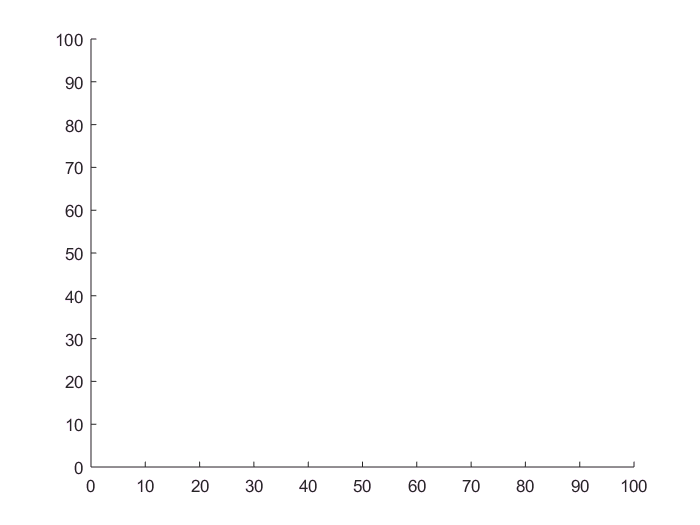

height = 100;
width = 100;
axis ([0 width 0 height]);

define starting and end point and iteration

qstart = [5,5];
qgoal = [95,75];
iterations = 10;

define tree edge, node and vertice

vertecies: An array of Vertrcies' coordinates, sorted by the generated order

vertecies = qstart;
vert_count = 1;

Edges:starting and ending of each edges, note edges(i) corresponds to vertecies(i+1), because vertecies(1) is the original point

edges_x = zeros(iterations,2);
edges_y = zeros(iterations,2);
edge_count = 0;

ind_nearest: index to the nearest point. vertecies(ind_nearest(i)) is the closetest vertex to vertecies(i+1)

ind_nearest = zeros(iterations,1);

define figure and hold

hold on;

%figure('name', 'RRT growing');
tic;

for i=1:iterations
    x_rand = width*rand();    % random point generation
    y_rand = height*rand();
    
    ind_nearest(i) = knnsearch(vertecies, [x_rand,y_rand]);
    
    
    vertecies(vert_count+1,:) = [x_rand, y_rand];
    vert_count = vert_count + 1;
    edges.x(edge_count+1,:) = [vertecies(ind_nearest(i),1), x_rand];
    edges.y(edge_count+1,:) = [vertecies(ind_nearest(i),2), y_rand];
    edge_count = edge_count + 1;
end

toc;

Elapsed time is 0.098253 seconds.


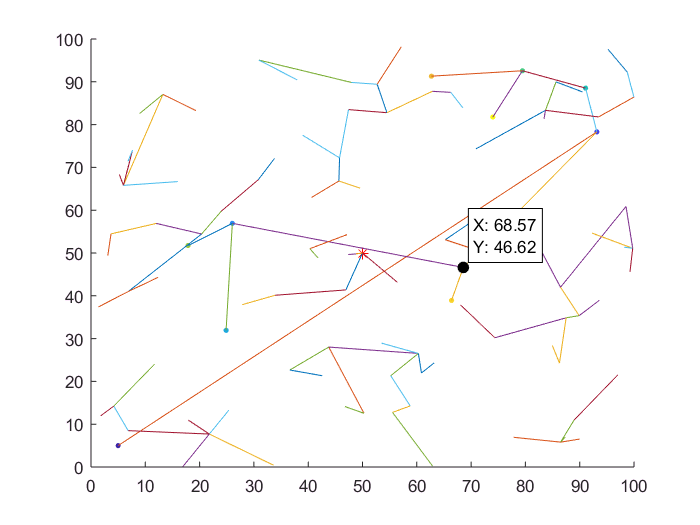

clear i x_rand y_rand edge_rand

figure('name', 'RRT basic');
scatter(origin(1), origin(2), 45, '*','r','LineWidth',1); hold on;
scatter(vertecies(:,1), vertecies(:,2), 10,linspace(1,10,length(vertecies(:,1))),'filled'); hold on;
plot(edges.x', edges.y');